**Giordano Dylan - Martelet Curtis                            L3 EEA_Gr TP1**

# Rapport TDP8: Convertisseurs continu-continu isolé Flyback

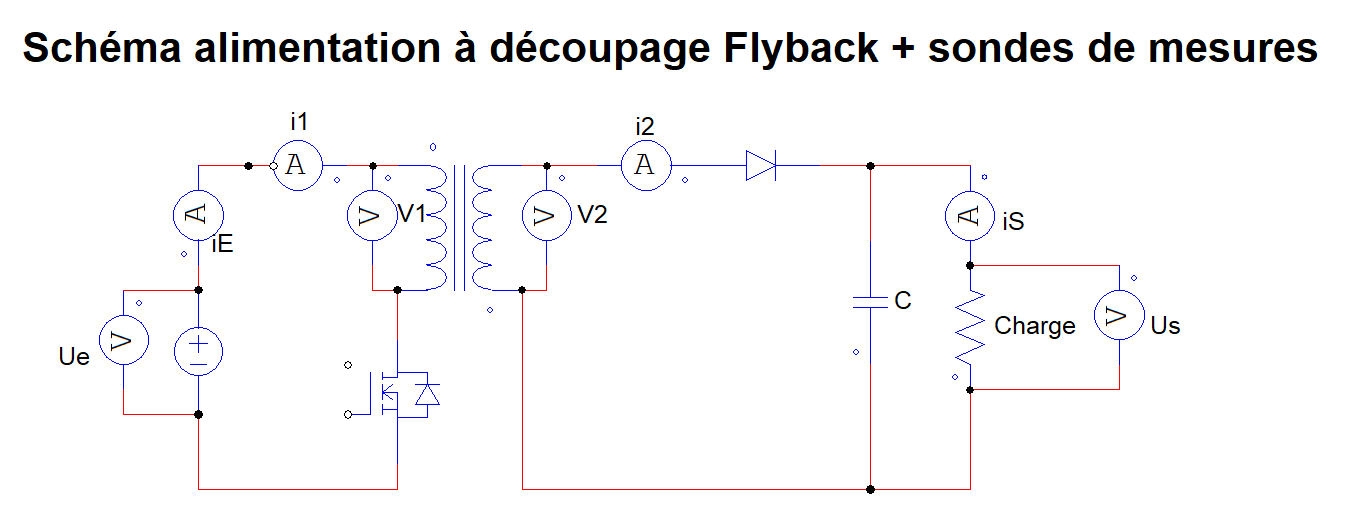

## 2.3) Fonctionnement en mode démagnétisation complète

$U_E =10V$ ; $F=20\textrm{kHz}$

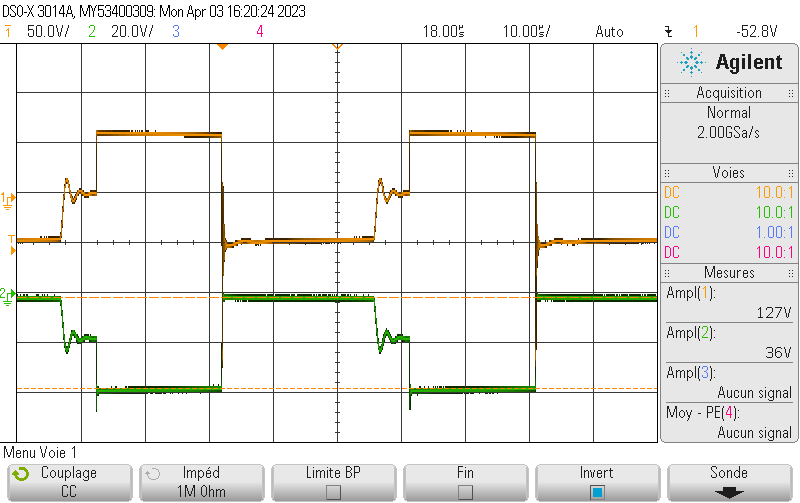

#### Orange $\Longrightarrow \;v_1 \left(t\right)$; Vert $\Longrightarrow \;v_2 \left(t\right)$

La tension V1 et V2 correspondent aux courbes théoriques du TD.

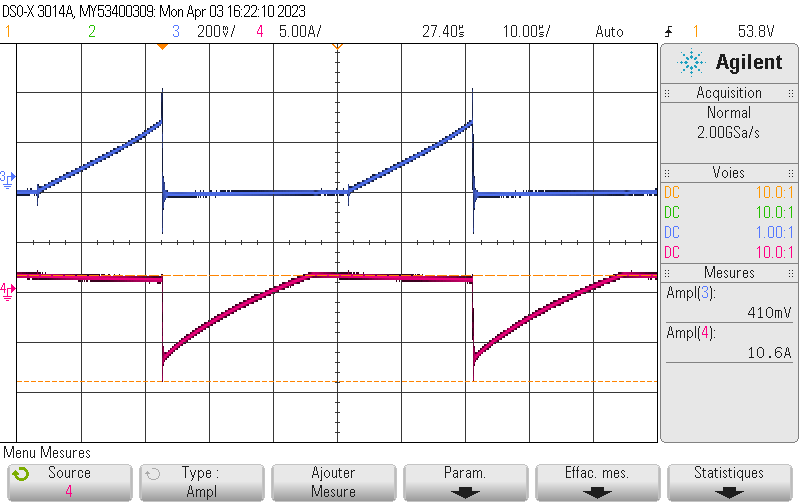

#### Bleu ${\Longrightarrow \;i}_1 \left(t\right)$; Rouge $\Longrightarrow \;i_2 \left(t\right)$

La courbe de I1 et I2 correspondent également à la théorie.

On est en régime démagnétisant complet. On mesure alpha =40% car l'oscilloscope n'arrive pas à mesurer le rapport cyclique.

On augmente $U_E$ pour que $U_E =60V$ ; $F=20\textrm{kHz}$.

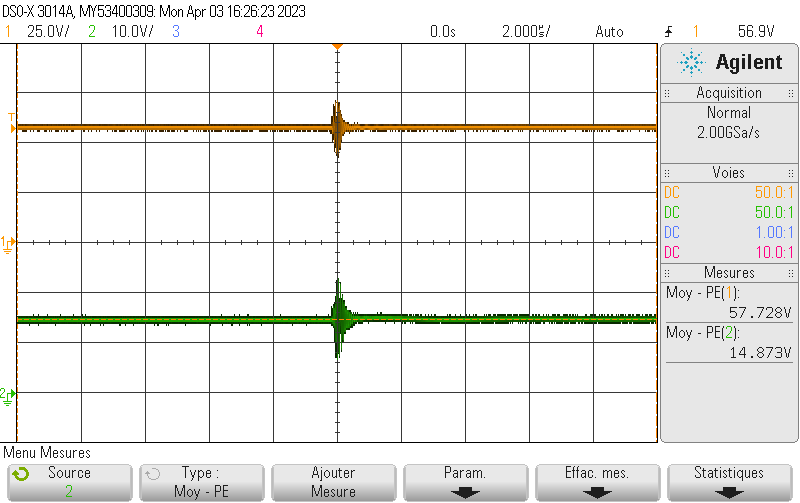

#### **Orange **${\Longrightarrow \;U}_E =57\ldotp 728V$ **; Vert **${\Longrightarrow \;V}_S =14\ldotp 874V$

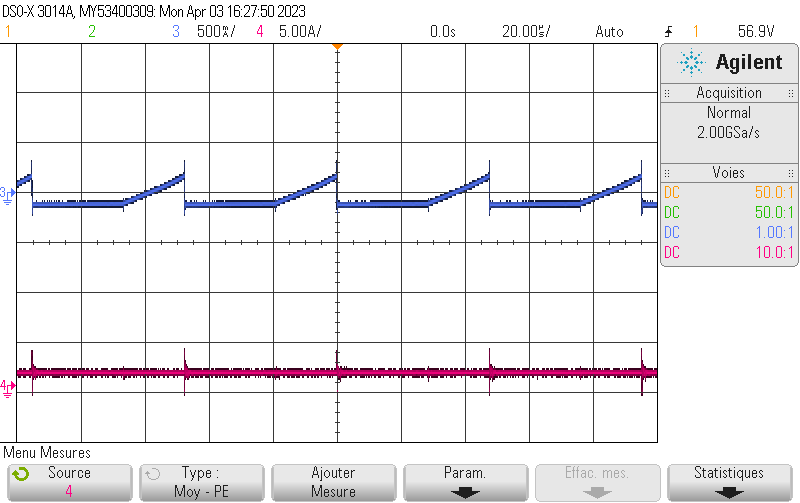

#### Bleu ${\Longrightarrow \;I}_E =0\ldotp 57A$ ; Rouge$\Longrightarrow \;I_S =1\ldotp 5A$

### Calcul de PE, PS et rendement:


$$P_E =U_E \times I_E =57\ldotp 728\times 0\ldotp 57=32\ldotp 9W$$



$$P_S =V_S \times I_S =14\ldotp 874\times 1\ldotp 5=22\ldotp 311W$$


$\mathrm{Rendement}=\frac{P_S }{P_E }=\frac{22\ldotp 311}{32\ldotp 9}=0\ldotp 68$, soit un rendement d'environ 68%.

%%MFaire la question sur le calcul des inductances

### Calcul de l'inductance:

$n_P =33$ spires ; $n_S =1$ spire ; $\mu =300$ ; $A_c =0\ldotp 377\mu H$


$$L_1 =\frac{\mu \times {N_1 }^2 \times A_c }{l_C }=\frac{300\times {33}^2 \times 0\ldotp 377e-6}{63\ldotp 5}=1\ldotp 9mH$$



$$L_2 =\frac{\mu \times {N_2 }^2 \times A_c }{l_C }=\frac{300\times 1\times 0\ldotp 377e-6}{63\ldotp 5}=1\ldotp 78\mu H$$


## 2.4) Fonctionnement en mode de démagnétisation incomplète

Pour $I_S =2A$, nous devons régler α :$\alpha =10\ldotp 6\times 24\ldotp 6\times 100=43\ldotp 08%$. Le rapport cyclique doit être réglé à 43.0

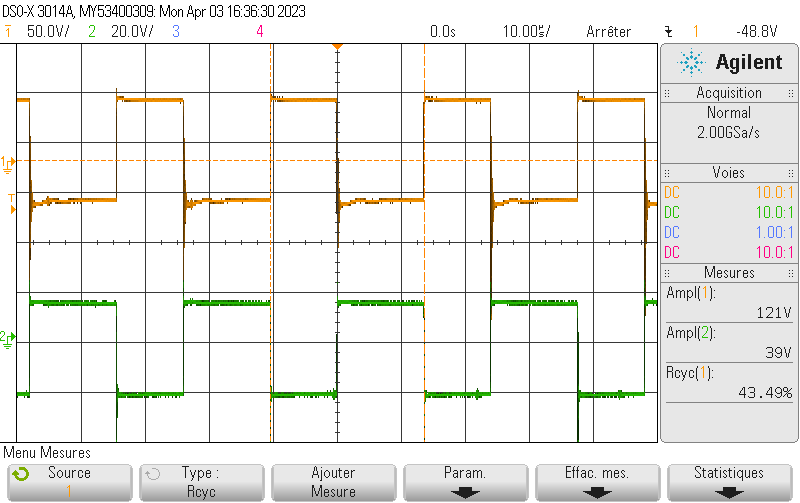

#### **Orange **${\Longrightarrow V}_1$ **; Vert **${\Longrightarrow \;V}_2$

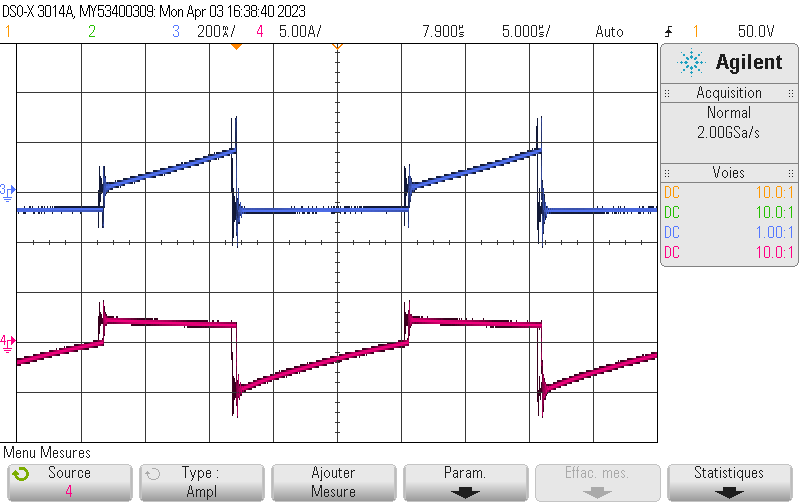

#### Bleu ${\Longrightarrow \;I}_1$ ; Rouge$\Longrightarrow \;I_2$

Le tracé de I1 et I2 a la même allure que la théorique.

## 2.5) Evolution de la tension de sortie en fonction de α

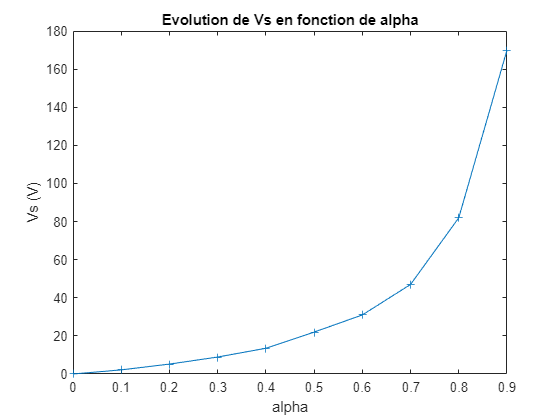

clear all;

Fdec=20e3;
Ue=60;

alpha=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9];
% th=50e-6.*alpha;
% Vs=[0 2.16]; %%Valeurs qu'on a pas eu le temps de faire


%%Valeurs rajoutées qui sont basé sur la théorie a vérifier.
Vs=[0 2.16 5.2 8.9 13.5 22 31 47 82 170];

plot(alpha*100,Vs,'+-');
title("Evolution de Vs en fonction de alpha");
xlabel('α (%)');
ylabel('Vs (V)');

On peut observer que la courbe de la tension Vs en fonction du rapport cyclique α est de la forme exponentielle: plus le rapport est élevé, plus la tension Vs est élevée.

Cependant, dans le cas de notre montage, on observe que pour α compris entre 0 et 50%, on est en mode de démagnétisation complet alors que si α est supérieur à 50%, le mode devient incomplet.

On peut donc supposer que l'efficacité du convertisseur est inversement proportionnel au rapport cyclique : plus le rapport cyclique est important, moins les bobines ont de temps pour se décharger et donc plus on a de perte.

%%%%%Tracé théorique car on avait pas le temps pour la pratique
N2=11;
N1=33;
Vsth=(N2./N1).*(alpha*Ue)./(1-alpha);
plot(alpha,Vsth);